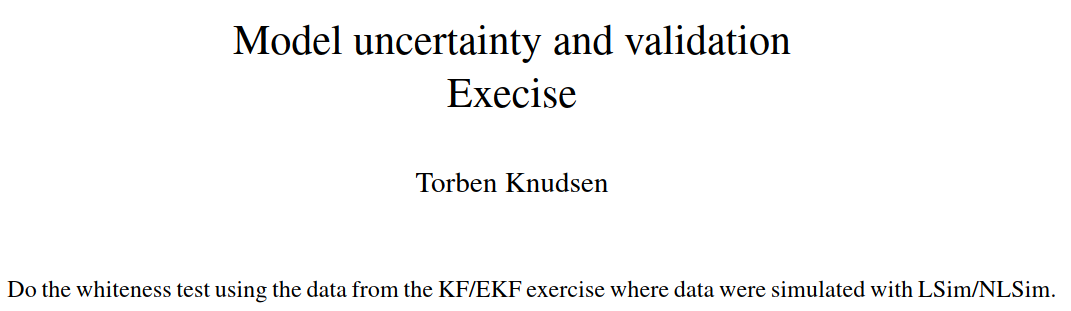

## Whiteness test for LSim

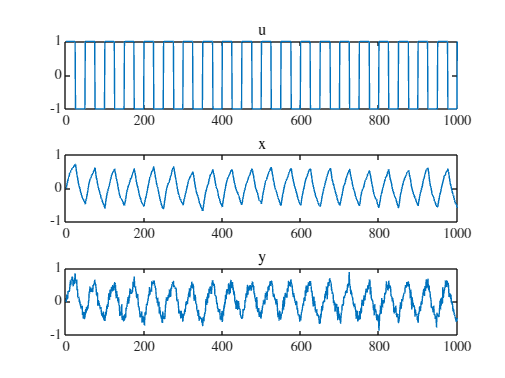

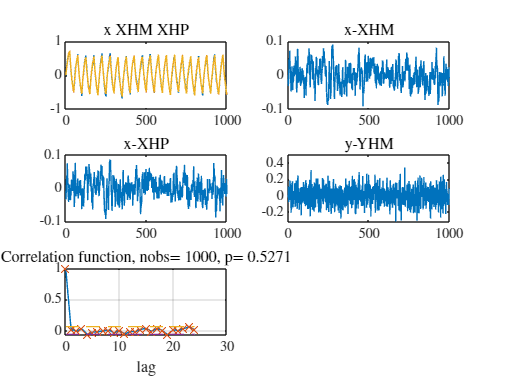

               ytm            xtm            xtp    
            __________    ___________    ___________

    Mean    0.00026317    -0.00035987    -0.00038483
    Std        0.10355       0.032122        0.03038
    MSE       0.010712      0.0010309     0.00092219



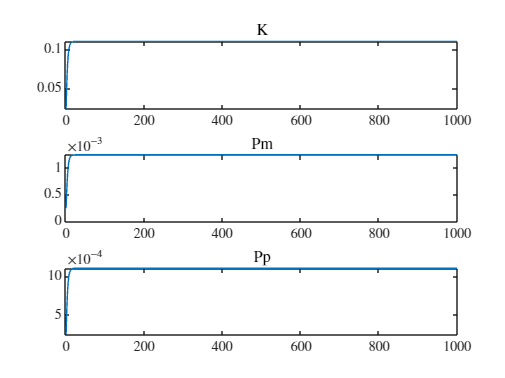

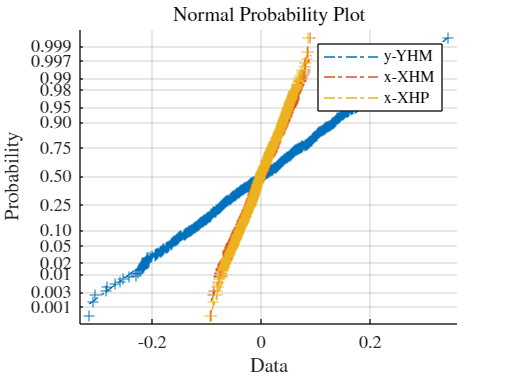

clear all; close all; clc;
LSim; KF;

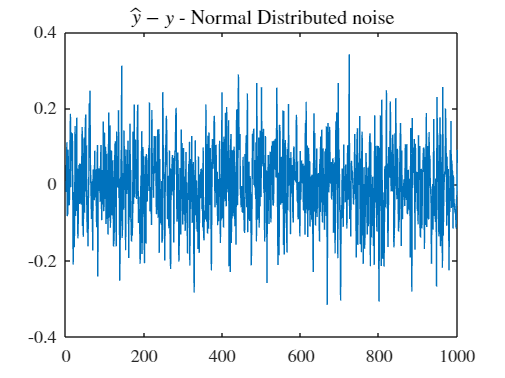


yres = y-YHM;
figure()
plot(yres)
title('$\hat{y}-y$ - Normal Distributed noise')

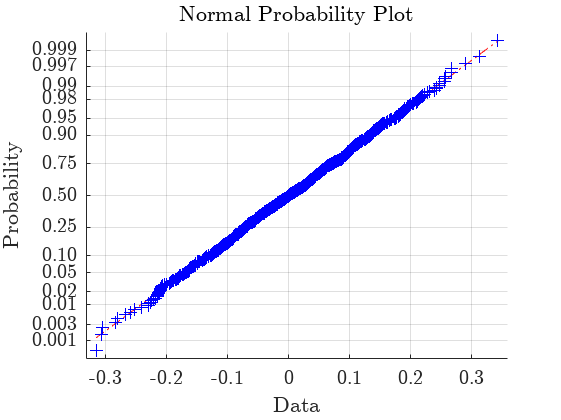

%normplot of output residuals
normplot(yres)

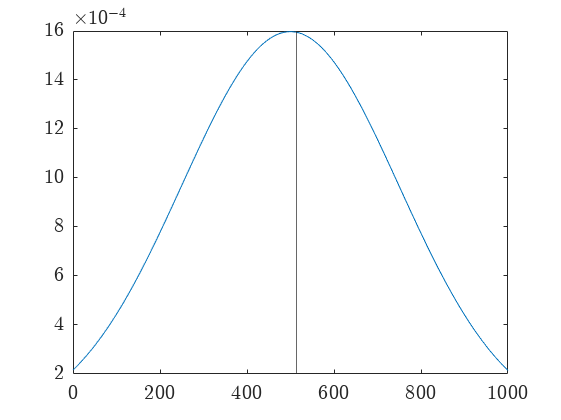


count = 0;
for i = 1:length(yres)-1
    if sign(yres(i+1)) ~= sign(yres(i))
        count = count +1;
    end
end

x = 0:1000;
y = normpdf(x,(length(yres)-1)/2,(length(yres)-1)/4);
figure()
plot(x,y)
xline(count)

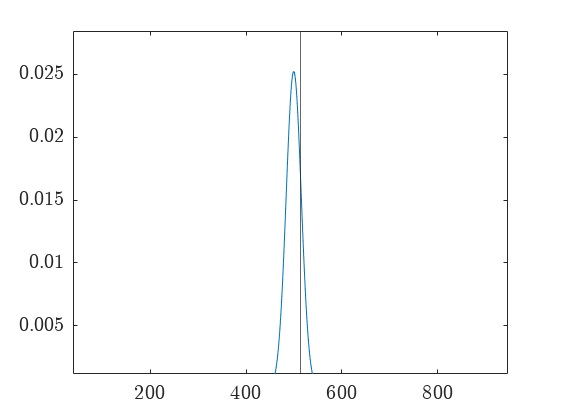


x = 0:1000-1;
y = binopdf(x,1000-1,.5);
figure()
plot(x,y)
xline(count)

              u          x           y    
            ______    ________    ________

    Mean     0.016    0.017249    0.014054
    Std     1.0004     0.33027     0.33402



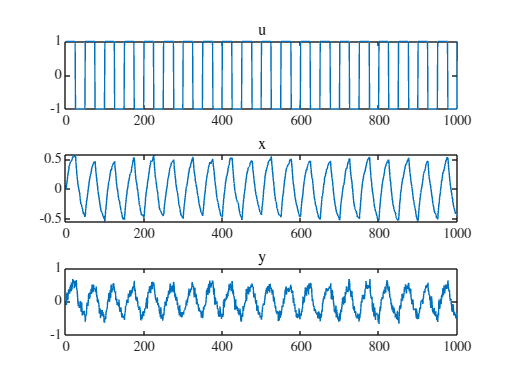

clear all; close all; clc;
NLSim;

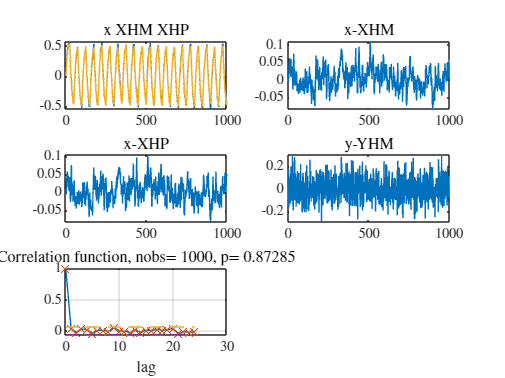

               ytm           xtm           xtp    
            __________    __________    __________

    Mean    0.00059112     0.0032519     0.0032288
    Std        0.10251        0.0303       0.02901
    MSE       0.010498    0.00092777    0.00085119



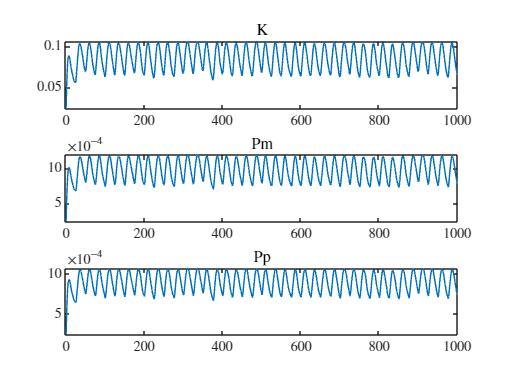

EKF;

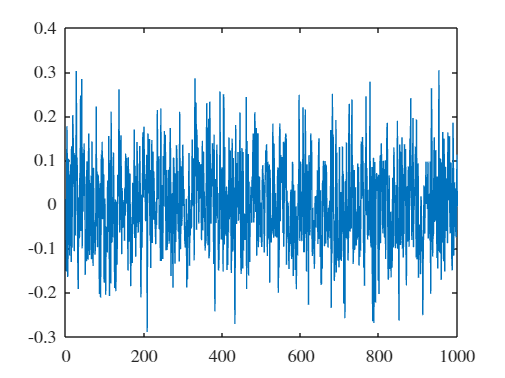

yres = y-YHM;
figure()
plot(yres)

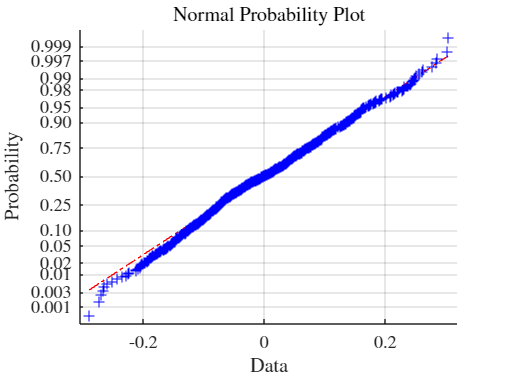

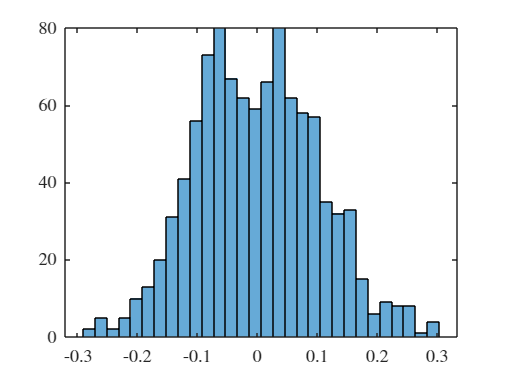

%normplot of output residuals
normplot(yres)

## What happens if the process and or measurement noise is uniform instead of normal?

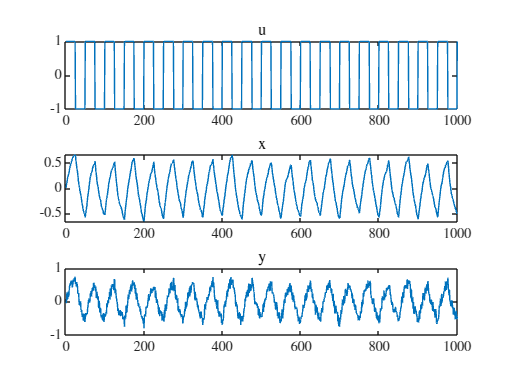

clear all;close all; clc;
LSim_uniform;

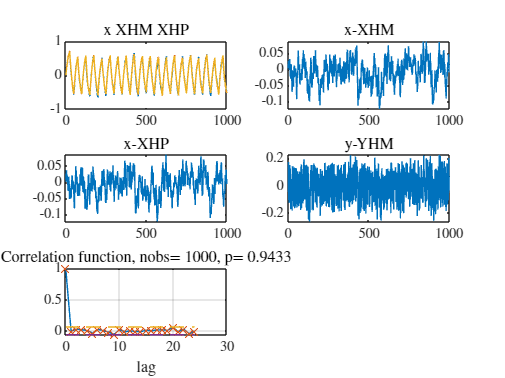

               ytm           xtm           xtp    
            __________    __________    __________

    Mean    -0.0070565    -0.0093078    -0.0085347
    Std        0.10588      0.037872      0.035893
    MSE       0.011249     0.0015195     0.0013599



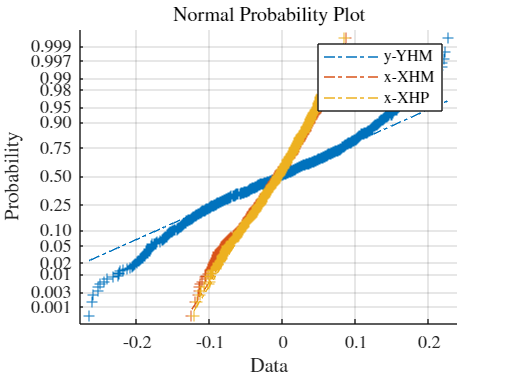

KF;

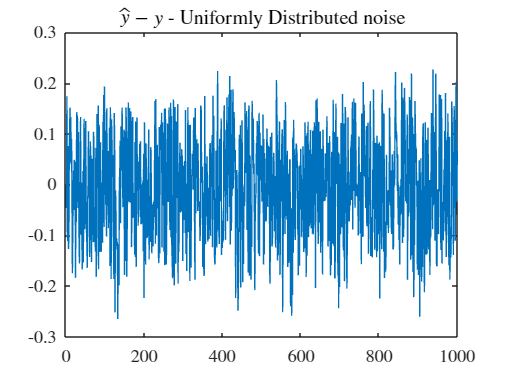

yres=y-YHM;
figure()
plot(yres)
title('$\hat{y}-y$ - Uniformly Distributed noise')

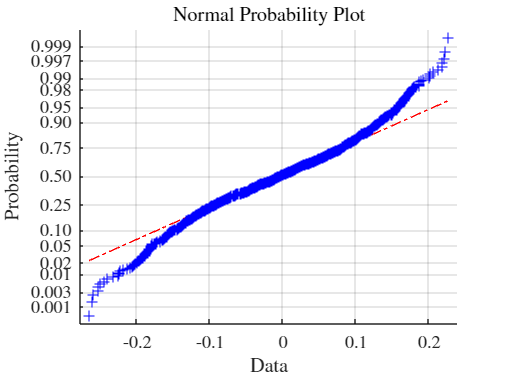

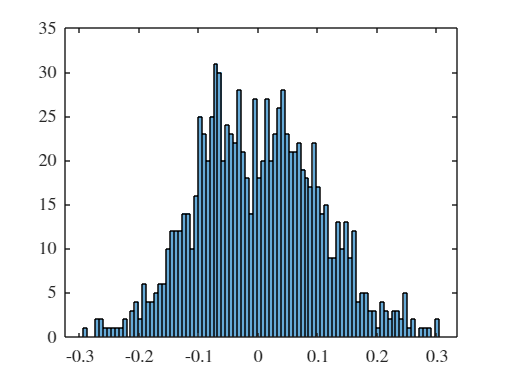

%Normalplot of residuals
normplot(yres)